clear; close all;

xcoeffs = [];
ycoeffs = [];


## Compute Bezier curves

x_positions = [];
y_positions = [];

figure;
axis equal
hold on
viscircles([0.24, 0.45; 0.43 0.45; 0.625, 0.45],[0.0675/2 0.0675/2 0.0675/2],'LineStyle','-','Color','black');
rectangle('position',[0 0 1 1])

xlim([-0.1 1.1])
ylim([-0.1 1.1])

### Section 1

Starting point

q0 = [0;0];
v0 = [0;0];

End point

q3 = [0.43;0.1];
v3 = [0;0];
t1 = 1;

q1 = q0 + v0.*t1/3;
q2 = q3 - v3.*t1/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 1")

Segment 1


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0, 0, 1.29, -0.86};
       cy = {0, 0, 0.3, -0.2};


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));

### Section 2

q0 = q3;
v0 = v3;

q3 = [0.24;0.45];
v3 = [0.4;3];
t2 = 0.4;

q1 = q0 + v0.*t2/3;
q2 = q3 - v3.*t2/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 2")

Segment 2


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0.43, 0, -0.73, 0.54};
       cy = {0.1, 0, -0.15, 0.5};


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));

### Section 3

q0 = q3;
v0 = v3;

q3 = [0.43;0.1];
v3 = [0;0];
t3 = 0.4;

q1 = q0 + v0.*t3/3;
q2 = q3 - v3.*t3/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 3")

Segment 3


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0.24, 0.16, 0.25, -0.22};
       cy = {0.45, 1.2, -3.45, 1.9};


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));

### Section 4

q0 = q3;
v0 = v3;

q3 = [0.43;0.45];
v3 = [0;4];
t4 = 0.4;

q1 = q0 + v0.*t4/3;
q2 = q3 - v3.*t4/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 4")

Segment 4


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0.43, 0, 0, 5.5511e-17};
       cy = {0.1, 0, -0.55, 0.9};


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));


### Section 5

q0 = q3;
v0 = v3;

q3 = [0.43;0.1];
v3 = [0;0];
t5 = 0.4;

q1 = q0 + v0.*t5/3;
q2 = q3 - v3.*t5/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 5")

Segment 5


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0.43, 0, 0, 5.5511e-17};
       cy = {0.45, 1.6, -4.25, 2.3};


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));


### Section 6

q0 = q3;
v0 = v3;

q3 = [0.625;0.45];
v3 = [-0.4;3];
t6 = 0.4;

q1 = q0 + v0.*t6/3;
q2 = q3 - v3.*t6/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 6")

Segment 6


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0.43, 0, 0.745, -0.55};
       cy = {0.1, 0, -0.15, 0.5};


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));


### Section 7

q0 = q3;
v0 = v3;

q3 = [0.43;0.1];
v3 = [0;0];
t7 = 0.3;

q1 = q0 + v0.*t7/3;
q2 = q3 - v3.*t7/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

disp("Segment 7")

Segment 7


fprintf("       cx = {"+ string(xcoeffs(end,1))+", "+string(xcoeffs(end,2))+", "+string(xcoeffs(end,3))+", "+string(xcoeffs(end,4))+ "};\n"+ ...
    "       cy = {"+ string(ycoeffs(end,1))+", "+string(ycoeffs(end,2))+", "+string(ycoeffs(end,3))+", "+string(ycoeffs(end,4))+ "};")

       cx = {0.625, -0.12, -0.345, 0.27};
       cy = {0.45, 0.9, -2.85, 1.6};

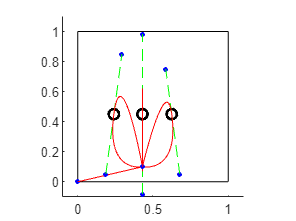


plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

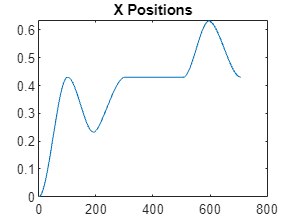


x_positions = cat(2, x_positions, xy1(1,:));
y_positions = cat(2, y_positions, xy1(2,:));

figure
plot(x_positions)
title("X Positions");

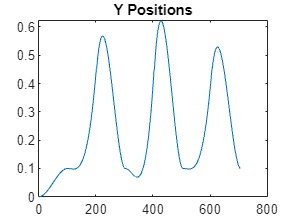


figure
plot(y_positions)
title("Y Positions");

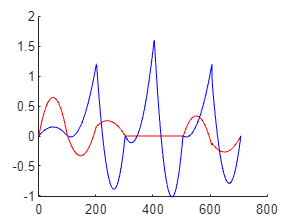

x_vel = [];
y_vel = [];
for n = 1:size(xcoeffs,1)
    u = 0:0.01:1;
    x_vel_new = xcoeffs(n,2) + xcoeffs(n,3)*2.*u + xcoeffs(n,4)*3*u.^2;
    y_vel_new = ycoeffs(n,2) + ycoeffs(n,3)*2.*u + ycoeffs(n,4)*3*u.^2;
    x_vel = [x_vel, x_vel_new];
    y_vel = [y_vel, y_vel_new];
end

figure;
hold on
plot(x_vel,'-r');
plot(y_vel,'-b');